# SmoothingSpline

A tension spline can be used to smooth noisy data and attempt to recover the "true" underlying function.

Let's start by defining a new function,

L = 10;
f = @(x) sin(2*pi*x/L);

create a grid of observation points,

N = 30;
x = linspace(0,L,N)';

and then sampling the function at the observation points while adding Gaussian noise,

sigma = 0.1;
y = f(x) + sigma*randn(N,1);

Let's create a dense grid in x just to better visualize the true function, and then plot the function and noisy observations,

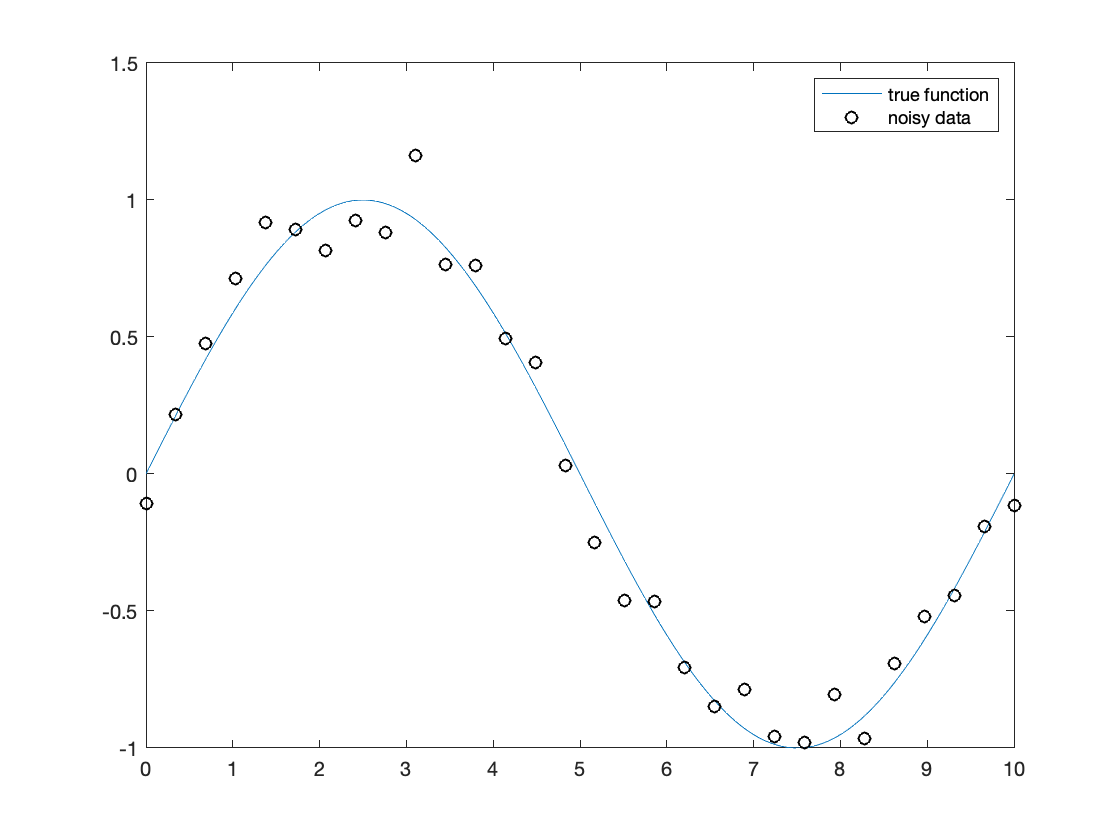

x_dense = linspace(0,L,10*N)';

figure
plot(x_dense,f(x_dense)), hold on
scatter(x,y,'k')
legend('true function', 'noisy data')

Finally, let's use a tension spline to try to smooth the data and plot the results,

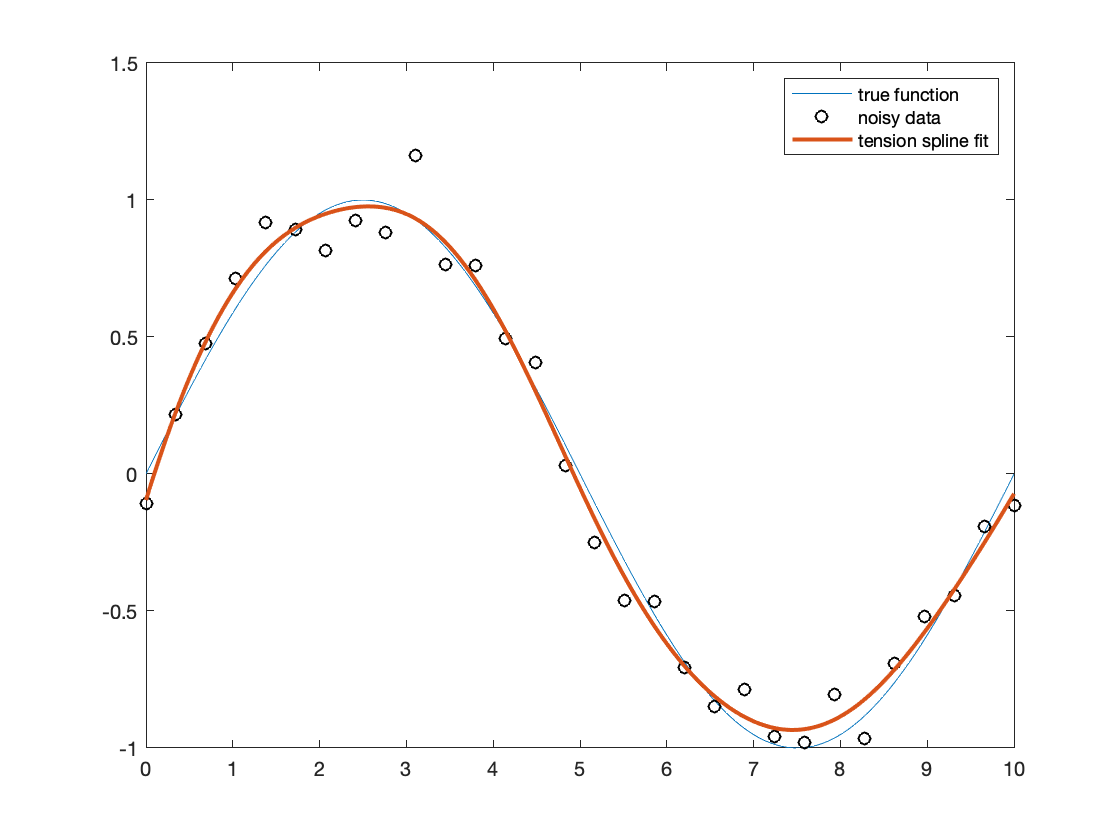

spline = SmoothingSpline(x,y,NormalDistribution(sigma));

figure
plot(x_dense,f(x_dense)), hold on
scatter(x,y,'k')
plot(x_dense,spline(x_dense),'LineWidth',2)
legend('true function', 'noisy data', 'tension spline fit')